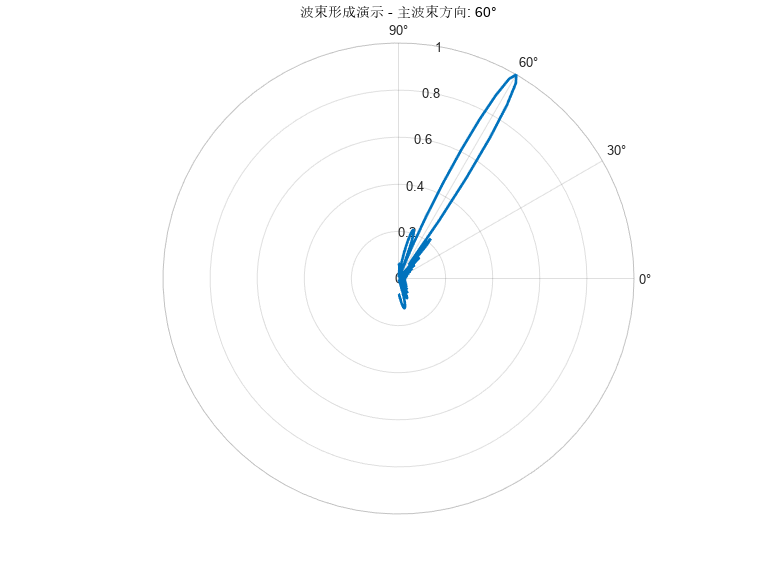

% 波束形成动态演示
clear all;
close all;

% 参数设置
c = 3e8; % 光速
f = 1e9; % 频率1GHz
lambda = c / f; % 波长
d = lambda / 2; % 阵元间距(半波长)
N = 32; % 阵元数量
theta = -90:1:90; % 扫描角度范围,另外一半是对称的，所以不用仿真
steering_angles = -60:10:60; % 主波束转向角度

% 创建图形窗口
figure('Position', [100 100 800 600]);

% 动态演示不同的波束方向
for steer = steering_angles
    % 计算相位差
    phase_shift = -2 * pi * d * sind(steer) / lambda;

    % 初始化方向图
    AF = zeros(size(theta));

    % 计算阵列方向图
    for i = 1:length(theta)
        % 计算每个方向的阵列因子
        phase = -2 * pi * d * sind(theta(i)) / lambda;
        array_vec = exp(1j * (0:N - 1) * (phase - phase_shift));
        AF(i) = abs(sum(array_vec)) / N;
    end

    % 绘制方向图
    polarplot(deg2rad(theta), AF, 'LineWidth', 2);
    title(['波束形成演示 - 主波束方向: ' num2str(steer) '°']);
    grid on;

    % 设置图形属性
    rlim([0 1]);
    rticks(0:0.2:1);
    thetaticks(-90:30:90);

    % 添加暂停使动画可见
    pause(0.5);
end

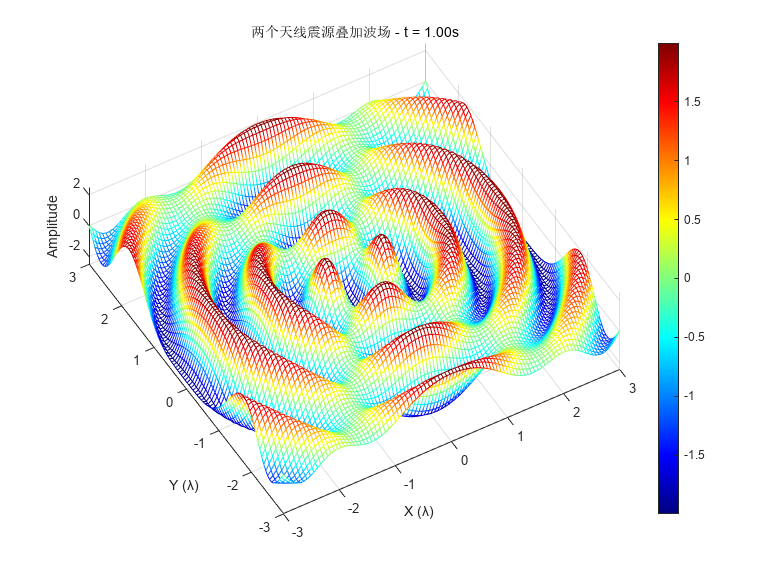

clear all;
close all;

% 参数设置
lambda = 1;
f = 3;
k = 2 * pi / lambda;
omega = 2 * pi * f;
phase_diff = 0;%可以修改相位差pi=180,pi/2=90
d = lambda;

% 空间和时间参数
x = linspace(-3 * lambda, 3 * lambda, 100);
y = linspace(-3 * lambda, 3 * lambda, 100);
[X, Y] = meshgrid(x, y);
dt = 0.02;
t = 0:dt:1;

% 源的位置
source1_pos = [-d / 2, 0];
source2_pos = [d / 2, 0];

% 创建图形窗口
figure('Position', [100 100 800 600]);

% 动态演示
for time = t
    % 计算到每个点的距离
    R1 = sqrt((X - source1_pos(1)) .^ 2 + (Y - source1_pos(2)) .^ 2);
    R2 = sqrt((X - source2_pos(1)) .^ 2 + (Y - source2_pos(2)) .^ 2);

    % 计算每个源的波场
    wave1 = cos(k * R1 - omega * time);
    wave2 = cos(k * R2 - omega * time + phase_diff);

    % 波场叠加
    total_wave = wave1 + wave2;

    % 使用mesh替代surf
    mesh(X, Y, total_wave, 'EdgeColor', 'interp');

    % 设置绘图属性
    zlim([-2.5 2.5]);
    xlabel('X (λ)');
    ylabel('Y (λ)');
    zlabel('Amplitude');
    title(['两个天线震源叠加波场 - t = ' num2str(time, '%.2f') 's']);
    colormap('jet');
    colorbar;

    % 设置视角
    view(-30, 75);

    % 添加源的位置标记（调整标记大小使其更显眼）
    hold on;
    plot3(source1_pos(1), source1_pos(2), 0, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
    plot3(source2_pos(1), source2_pos(2), 0, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
    hold off;

    % 添加网格
    grid on;

    % 更新显示
    drawnow;
end